**This work is based on **[ATLAS Open Data](https://opendata.atlas.cern/).

`Import CSV file locally and read as table:`

data = readtable('Hyy.csv');

`Important elements include:`

***photon_pt***：`transverse momentum of the photon`

***photon_eta***：`pseudorapidity of the photon`

***photon_phi***：`azimuthal angle of the photon in the transverse plane`

***photon_E***：`energy of the photon`

photon_isTightID：`photon tight identification flag, used to identify well-reconstructed photons`

photon_etcone20：`transverse energy isolation of the photon`

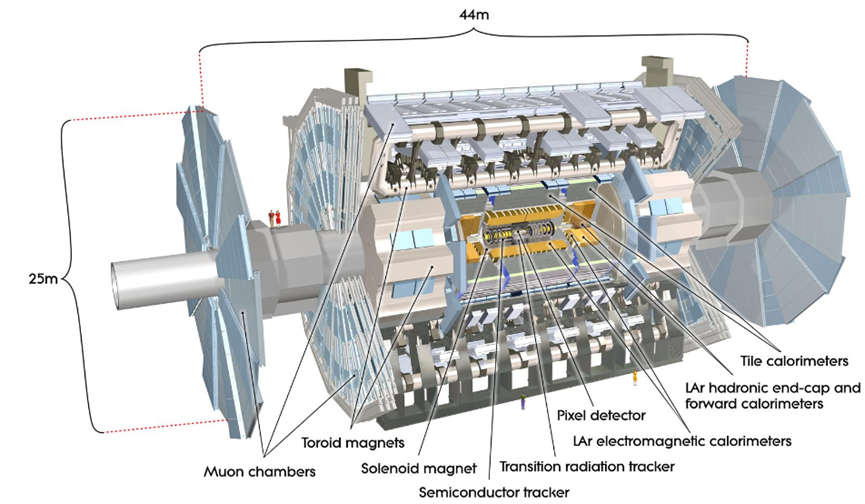

**Figure 1：ATLAS Detector layout**

`Calculate diphoton invariant mass formula`**：**

`Select the` $H\to \gamma \gamma$ `decay channel for analysis. Preliminary event selection has been completed,and the data we obtained directly corresponds to the results of this decay channel.`

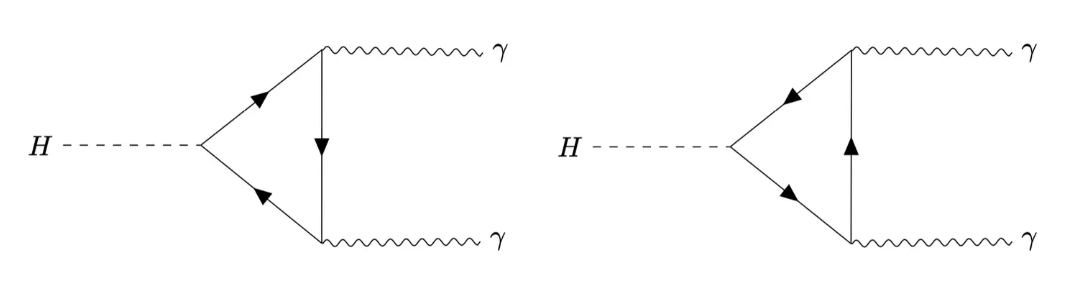

**Figure 2：**`Feynman diagram of the `$H\to \gamma \gamma$ `decay mode`

`From four-momentum conservation, we know how to calculate the invariant mass of the diphoton final state:`


$$M^{2}=(E_{1}+E_{2})^{2}-\left\|\mathbf {p} _{1}+\mathbf {p} _{2}\right\|^{2}$$


`In the formula, we reconstruct the three-dimensional momentum using the azimuthal angle φ and pseudorapidity η:`


$$p_t =\sqrt{p_x^2 +p_y^2 }$$



$$\begin{array}{l}
p_x =p_{t\;} \cdot \cos \left(\phi \right)\\
p_y =p_{t\;} \cdot \sin \left(\phi \right)\\
p_z =p_t \cdot \sinh \left(\eta \right)
\end{array}$$


`Finally, we divide by 1000 to convert units to GeV.`

calc_myy = @(pt, eta, phi, E) sqrt((E(1)+E(2))^2 - ...
    sum([pt(1).*cos(phi(1)) + pt(2).*cos(phi(2)), ...
    pt(1).*sin(phi(1)) + pt(2).*sin(phi(2)), ...
    pt(1).*sinh(eta(1)) + pt(2).*sinh(eta(2))].^2))/1000;


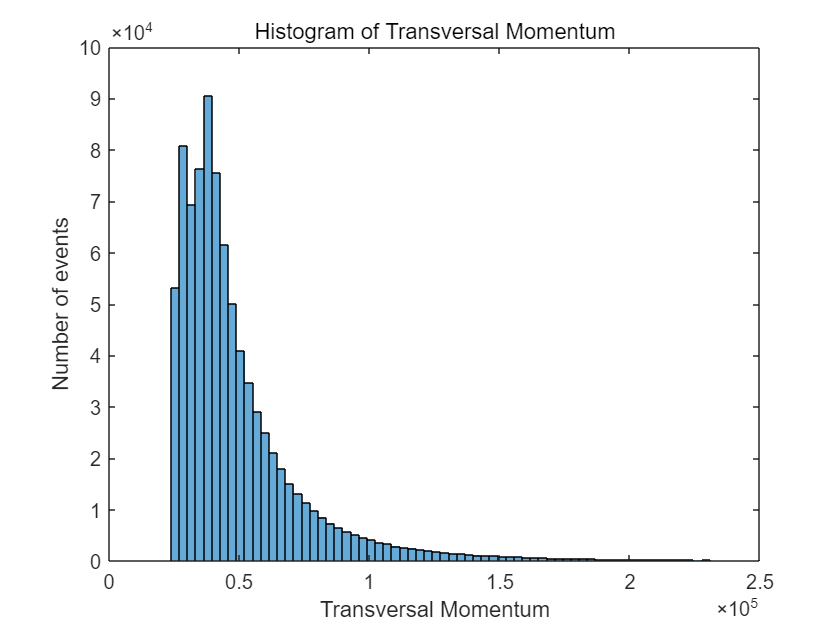

px=data.photon_pt.*cos(data.photon_phi);
py=data.photon_pt.*sin(data.photon_phi);
pz=data.photon_pt.*sinh(data.photon_eta);
ptr=sqrt(px.^2+py.^2);

Pt=[px,py];
Pxz=[px,pz];
Pyz=[py,pz];
Ptz=[ptr,pz];
EPz=[data.photon_E,abs(pz)];
EPt=[data.photon_E,abs(ptr)];

figure;
histogram(ptr,500);
xlim([0,2.5*10^5])
xlabel('Transversal Momentum');
ylabel('Number of events');
title('Histogram of Transversal Momentum');

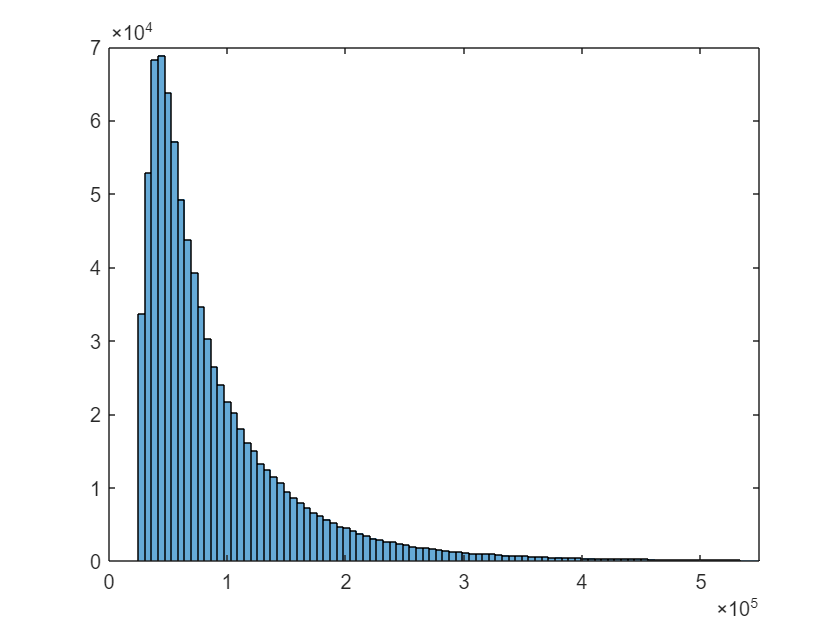

figure;
histogram(data.photon_E,500);
xlim([0,5.5*10^5])

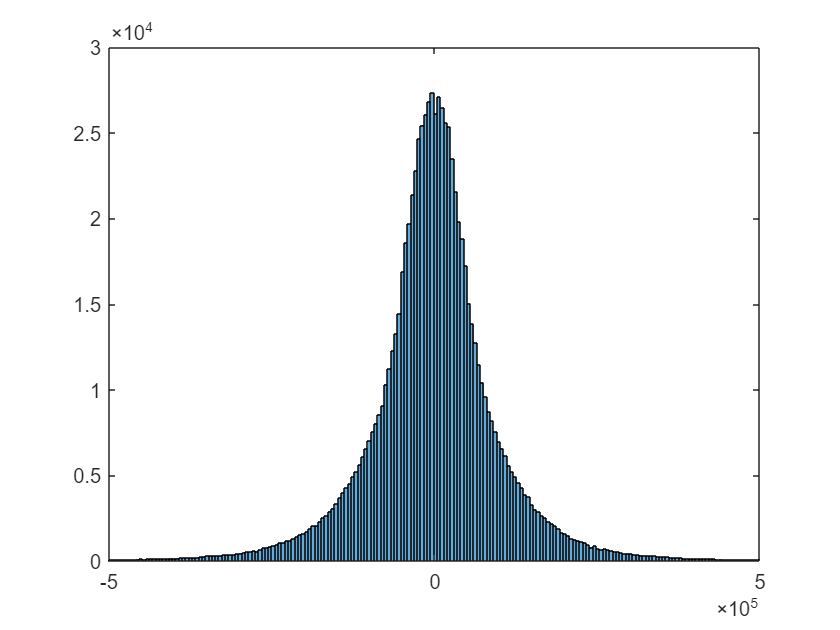

%xlabel('Transversal Momentum');
%ylabel('Number of events');
%title('Histogram of Transversal Momentum');

figure;
histogram(pz,1000);
xlim([-0.5*10^6,0.5*10^6])

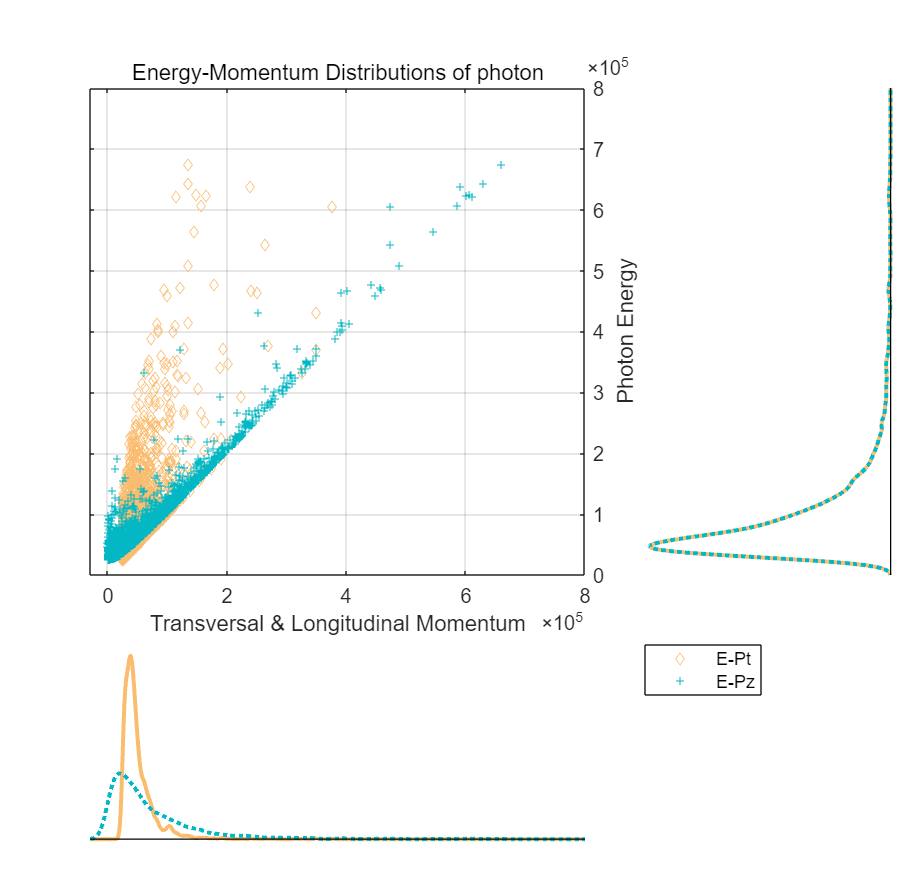

nRows = 862157; 
sampleSize = 2000; 

indices = randsample(nRows, sampleSize);

SDz = EPz(indices,:);
SDt = EPt(indices,:);

species1 = repmat({'E-Pt'}, sampleSize, 1); 
species2 = repmat({'E-Pz'}, sampleSize, 1);  

meas = [SDt; SDz];   

species = [species1; species2]; 

x = meas(:,2);  
y = meas(:,1);  

figure('Position', [100, 100, 600, 590]);
scatterhist(x, y, 'Group', species, 'Kernel', 'on', 'Location', 'SouthEast', ...
     'Color',[0.98,0.74,0.44;0.01,0.72,0.77], 'LineStyle', {'-', ':'}, ...
    'LineWidth',[2,2],'Marker','d+','MarkerSize',[4,4]);

grid on;
xlabel('Transversal & Longitudinal Momentum');
xlim([-0.3*10^(5),8*10^5])
ylabel('Photon Energy');
ylim([0,8*10^5])
title('Energy-Momentum Distributions of photon');

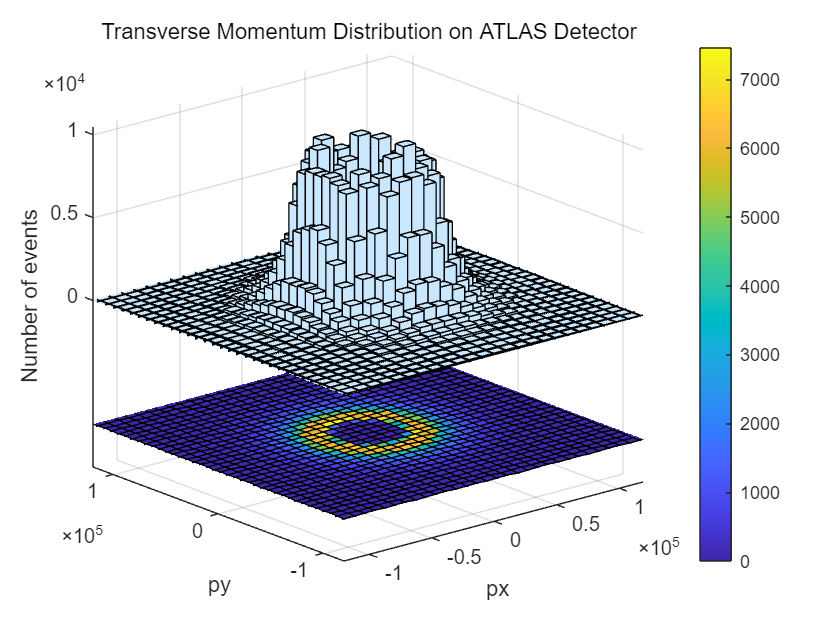

figure;
hist3(Pt,[250,250])
xlabel('px')
ylabel('py')
zlabel('Number of events')
%colorbar
xlim([-1.2*10^5,1.2*10^5])
ylim([-1.2*10^5,1.2*10^5])
hold on
N = hist3(Pt,[300,300]);
N_pcolor = N';
N_pcolor(size(N_pcolor,1)+1,size(N_pcolor,2)+1) = 0;
pxl = linspace(min(px),max(px),size(N_pcolor,2)); % Columns of N_pcolor
pyl = linspace(min(py),max(py),size(N_pcolor,1)); % Rows of N_pcolor
h = pcolor(pxl,pyl,N_pcolor);
colormap('parula') % Change color scheme 
colorbar % Display colorbar
h.ZData = -max(N_pcolor(:))*ones(size(N_pcolor));
ax = gca;
ax.ZTick(ax.ZTick < 0) = [];
title('Transverse Momentum Distribution on ATLAS Detector');
view([-40,20])
hold off

`Explore data composition and modify data structure:`

data(1:6,:)

ans = 6×8 table
    entry    subentry    photon_pt    photon_eta    photon_phi     photon_E     photon_isTightID    photon_etcone20
    _____    ________    _________    __________    __________    __________    ________________    _______________

      0         0          46690        -1.7791       -2.1865     1.4225e+05           -1               1209.2     
      0         1          29443         1.1681        1.1274          51918           -1               575.04     
      1         0          60889        0.17412        1.8595          61814           -1               5396.2     
      1         1          37795       -0.96896      -0.88825          56970           -1               2005.3     
      2         0          39186        0.13934        1.0165          39567           -1               3261.8     
      2         1          25327        -1.3091       -1.7879          50310           -1                21145     


photon_pt0 = data(data.subentry == 0 , :).photon_pt;
photon_pt1 = data(data.subentry == 1 , :).photon_pt;

photon_eta0 = data(data.subentry == 0 , :).photon_eta;
photon_eta1 = data(data.subentry == 1 , :).photon_eta;

photon_phi0 = data(data.subentry == 0 , :).photon_phi;
photon_phi1 = data(data.subentry == 1 , :).photon_phi;


photon_E0 = data(data.subentry == 0 , :).photon_E;
photon_E1 = data(data.subentry == 1 , :).photon_E;

photon_isTightID0 = data(data.subentry == 0 , :).photon_isTightID;
photon_isTightID1 = data(data.subentry == 1 , :).photon_isTightID;

photon_etcone200 = data(data.subentry == 0 , :).photon_etcone20;
photon_etcone201 = data(data.subentry == 1 , :).photon_etcone20;


dataN=[photon_pt0,photon_pt1,photon_eta0,photon_eta1,...
    photon_phi0,photon_phi1,photon_E0, photon_E1,...
    photon_isTightID0,photon_isTightID1,photon_etcone200,photon_etcone201];
column_names = {'photon_pt0', 'photon_pt1','photon_eta0','photon_eta1',...
    'photon_phi0','photon_phi1','photon_E0', 'photon_E1',...
    'photon_isTightID0','photon_isTightID1','photon_etcone200','photon_etcone201'};
dataN = array2table(dataN, 'VariableNames', column_names);
dataN(1:3,:)

ans = 3×12 table
    photon_pt0    photon_pt1    photon_eta0    photon_eta1    photon_phi0    photon_phi1    photon_E0     photon_E1    photon_isTightID0    photon_isTightID1    photon_etcone200    photon_etcone201
    __________    __________    ___________    ___________    ___________    ___________    __________    _________    _________________    _________________    ________________    ________________

      46690         29443         -1.7791         1.1681        -2.1865         1.1274      1.4225e+05      51918             -1                   -1                 1209.2              575.04     
      60889         37795         0.17412       -0.96896         1.8595       -0.88825           61814      56970             -1                   -1                 5396.2              2005.3     
      39186         25327         0.13934        -1.3091         1.0165        -1.7879           39567      50310             -1                   -1                 3261.8               211

`Apply cuts and calculate invariant mass for each photon pair:`

condition1 = dataN.photon_isTightID0 == 1 & dataN.photon_isTightID1 == 1;
condition2 = dataN.photon_pt0 > 40000 & dataN.photon_pt1 > 30000;
condition3 = dataN.photon_etcone200 < 4000 & dataN.photon_etcone201 < 4000;
condition4 = ((abs(dataN.photon_eta0) > 1.52 | abs(dataN.photon_eta0) < 1.37) & ...
             (abs(dataN.photon_eta1)>1.52 | abs(dataN.photon_eta1)<1.37));

filtered_data = dataN(condition1 & condition2 & condition3 & condition4, :);

myy = arrayfun(@(i) calc_myy([filtered_data.photon_pt0(i), filtered_data.photon_pt1(i)], ...
    [filtered_data.photon_eta0(i), filtered_data.photon_eta1(i)], ...
    [filtered_data.photon_phi0(i), filtered_data.photon_phi1(i)], ...
    [filtered_data.photon_E0(i), filtered_data.photon_E1(i)]), ...
    (1:height(filtered_data))');


`Plot a preliminary histogram of invariant mass distribution:`

`First, define some initial histogram settings`

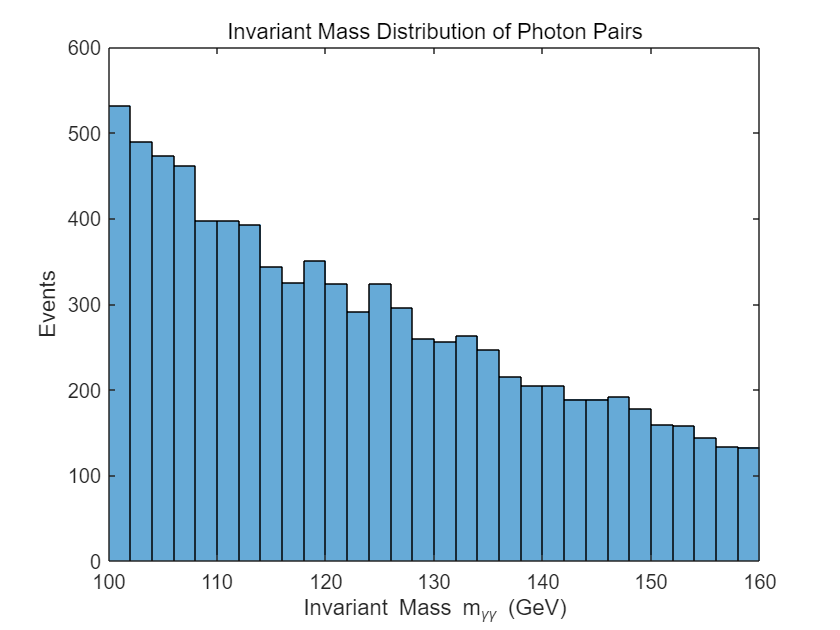

xmin = 100; % GeV
xmax = 160; % GeV
step_size = 2; % GeV

bin_edges = xmin:step_size:xmax; 
bin_centres = xmin + step_size/2:step_size:xmax - step_size/2;

figure;
h = histogram(myy, bin_edges);
xlabel('Invariant Mass m_{\gamma\gamma} (GeV)');
xlim([100,160])
ylabel('Events');
title('Invariant Mass Distribution of Photon Pairs');

`From the results above, the signal peak is not prominent. Next, we perform fitting of the signal and background to more intuitively present the physical results.`

`Calculate statistical errors:`

`In particle physics experiments, there is a standard rule for determining statistical errors in event counts. We typically assume that the count data in a given bin follows a Poisson distribution:`


$${\displaystyle P(X=k)={\frac {e^{-\lambda }\lambda ^{k}}{k!}}}$$


`The characteristic of the Poisson distribution is that its mean equals its variance. `

`Therefore, statistical errors can be estimated by taking the square root of the event count in that bin.` 

`This also facilitates plotting error bars.`

data_x = h.Values;
data_x_errors = sqrt(data_x);
data_x_errors(data_x_errors == 0) = 1; 

`Perform signal and background fitting:`

`A 4th-order polynomial function models the smooth background, and a Gaussian peak models signal events:`：

% Custom composite model including polynomial and Gaussian functions
% x - independent variable, p0-p4 - 4th-order polynomial coefficients,
% A - amplitude, mu - mean, sigma - standard deviation
gausspoly = fittype('p0 + p1*x + p2*x^2 + p3*x^3 + p4*x^4 + A*exp(-((x-mu)^2)/(2*sigma^2))',...
                    'independent', 'x', 'coefficients', ...
                    {'p0', 'p1', 'p2', 'p3', 'p4', 'A', 'mu', 'sigma'});

startPoints = [1000,0, 0, 0, 0, 90, 125.09, 2]; 
[coeff, gof] = fit(bin_centres', data_x', gausspoly, 'Start', startPoints, ...
                    'Weights', 1./(data_x_errors'.^2));

out=feval(coeff, bin_centres);

sigfit=coeff.A*exp(-((bin_centres'-coeff.mu).^2)/(2*coeff.sigma^2));

background = coeff.p0 + coeff.p1*bin_centres' + coeff.p2*(bin_centres').^2 + ...
             coeff.p3*(bin_centres').^3 + coeff.p4*(bin_centres').^4;

signal=data_x'-background; 


`Plot histogram, signal/background fitting curves, and residual plot:`

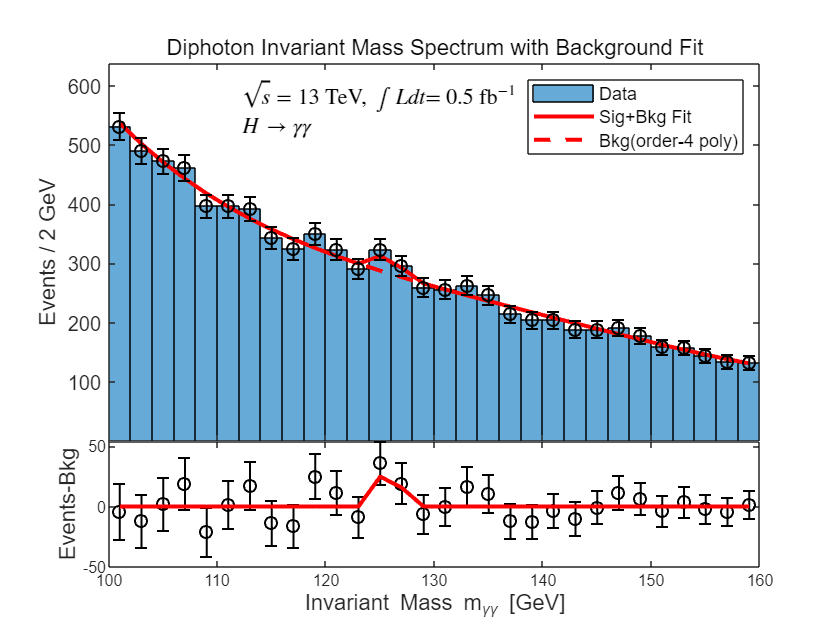

figure;

axes1 = axes('Position',[0.13, 0.3, 0.775, 0.6]);

h = histogram(myy, bin_edges);
hold on;

plot(bin_centres, out, 'r-', 'LineWidth', 2);

plot(bin_centres, background, 'r--', 'LineWidth', 2);

errorbar(bin_centres, data_x, data_x_errors, 'ko', 'LineWidth', 1);

ylabel('Events / 2 GeV');
title('Diphoton Invariant Mass Spectrum with Background Fit');
xlim([xmin, xmax]);
ylim([0.1, max(data_x)*1.2]);

legend('Data','Sig+Bkg Fit', 'Bkg(order-4 poly)');


text(xmin + (xmax-xmin)*0.2, max(data_x)*1.1, ...
    '$\sqrt{s} = 13$ TeV, $\int L dt $= 0.5 fb$^{-1}$','Interpreter','latex', 'FontSize', 11);
text(xmin + (xmax-xmin)*0.2, max(data_x)*1.0, ...
    '$H \rightarrow \gamma \gamma$','Interpreter','latex', 'FontSize', 11);

hold off;

axes2 = axes('Position',[0.13, 0.1, 0.775, 0.2]);

errorbar(bin_centres, signal, data_x_errors, 'ko', 'LineWidth', 1);
hold on;

plot(bin_centres, sigfit, 'r-', 'LineWidth', 2);

xlabel('Invariant Mass m_{\gamma\gamma} [GeV]','FontSize', 11);
ylabel('Events-Bkg','FontSize', 11);
hold off;

linkaxes([axes1, axes2], 'x');
set(axes1, 'XTickLabel',[], 'XTick', get(axes2, 'XTick'), 'XLim', get(axes2, 'XLim'));
hold off;